# Hello World для компьютерного зрения

- **Данные**

- **Архитектура**

- **Обучение**

- **Валидация **

### **Данные**

Путь к изображениям

root = matlabroot;
path = "/toolbox/nnet/nndemos/nndatasets/DigitDataset";
path2digits = root+path;


ImageDatastore

imds = imageDatastore(path2digits,"IncludeSubfolders",true,"LabelSource","foldernames");
[train_data, test_data] = imds.splitEachLabel(0.8,'randomized');
[test_data, val_data] = test_data.splitEachLabel(0.5,'randomized');

### Архитектура

layers = [imageInputLayer([28,28,1])
    convolution2dLayer(5,20)
    reluLayer
    maxPooling2dLayer(2,"Stride",2)
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

### Обучение

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:05 |       14.06% |       10.40% |      12.9345 |      13.1077 |          0.0100 |


|       1 |          30 |       00:00:13 |       40.63% |              |       3.7827 |              |          0.0100 |


|       1 |          50 |       00:00:17 |       53.13% |       60.10% |       2.6480 |       2.0617 |          0.0100 |


|       1 |          60 |       00:00:19 |       63.28% |              |       1.7010 |              |          0.0100 |


|       2 |          90 |       00:00:25 |       58.59% |              |       2.1354 |              |          0.0100 |


|       2 |         100 |       00:00:27 |       75.00% |       70.50% |       0.9301 |       1.5171 |          0.0100 |


|       2 |         120 |       00:00:31 |       75.78% |              |       1.2839 |              |          0.0100 |


|       3 |         150 |       00:00:37 |       89.84% |       81.30% |       0.6270 |       1.0649 |          0.0100 |


|       3 |         180 |       00:00:42 |       83.59% |              |       0.8313 |              |          0.0100 |


|       4 |         200 |       00:00:47 |       83.59% |       83.40% |       0.7210 |       1.0301 |          0.0100 |


|       4 |         210 |       00:00:49 |       91.41% |              |       0.4838 |              |          0.0100 |


|       4 |         240 |       00:00:54 |       95.31% |              |       0.3734 |              |          0.0100 |


|       5 |         250 |       00:00:57 |       93.75% |       89.50% |       0.2387 |       0.7035 |          0.0100 |


|       5 |         270 |       00:01:01 |       94.53% |              |       0.1998 |              |          0.0100 |


|       5 |         300 |       00:01:06 |       88.28% |       92.20% |       0.8548 |       0.5933 |          0.0100 |


|       6 |         330 |       00:01:12 |       93.75% |              |       0.3153 |              |          0.0100 |


|       6 |         350 |       00:01:16 |       97.66% |       90.60% |       0.2622 |       0.7117 |          0.0100 |


|       6 |         360 |       00:01:18 |       87.50% |              |       0.6808 |              |          0.0100 |


|       7 |         390 |       00:01:24 |       92.97% |              |       0.4389 |              |          0.0100 |


|       7 |         400 |       00:01:26 |       89.06% |       92.10% |       0.9804 |       0.7919 |          0.0100 |


|       7 |         420 |       00:01:30 |       96.88% |              |       0.2241 |              |          0.0100 |


|       8 |         450 |       00:01:36 |       96.09% |       91.30% |       0.2439 |       0.8156 |          0.0100 |


|       8 |         480 |       00:01:42 |       98.44% |              |       0.1473 |              |          0.0100 |


|       9 |         500 |       00:01:46 |       91.41% |       91.10% |       0.8618 |       1.1408 |          0.0100 |


|       9 |         510 |       00:01:49 |       97.66% |              |       0.2148 |              |          0.0100 |


|       9 |         540 |       00:01:55 |       95.31% |              |       0.5016 |              |          0.0100 |


|       9 |         550 |       00:01:57 |       95.31% |       96.20% |       0.3780 |       0.2786 |          0.0100 |


|      10 |         570 |       00:02:01 |       93.75% |              |       0.3661 |              |          0.0100 |


|      10 |         600 |       00:02:07 |       91.41% |       92.50% |       0.9858 |       0.6569 |          0.0100 |


|      11 |         630 |       00:02:12 |       96.09% |              |       0.2312 |              |          0.0100 |


|      11 |         650 |       00:02:17 |      100.00% |       96.70% |   8.9814e-05 |       0.3059 |          0.0100 |


|      11 |         660 |       00:02:18 |       97.66% |              |       0.2437 |              |          0.0100 |


|      12 |         690 |       00:02:24 |       93.75% |              |       0.3290 |              |          0.0100 |


|      12 |         700 |       00:02:26 |       99.22% |       93.30% |       0.0282 |       0.6904 |          0.0100 |


|      12 |         720 |       00:02:29 |       95.31% |              |       0.3988 |              |          0.0100 |


|      13 |         750 |       00:02:36 |       99.22% |       96.70% |       0.0452 |       0.2387 |          0.0100 |


|      13 |         780 |       00:02:41 |       97.66% |              |       0.3061 |              |          0.0100 |


|      13 |         800 |       00:02:45 |       94.53% |       97.00% |       0.6765 |       0.3078 |          0.0100 |


|      14 |         810 |       00:02:47 |      100.00% |              |       0.0019 |              |          0.0100 |


|      14 |         840 |       00:02:53 |       96.09% |              |       0.3421 |              |          0.0100 |


|      14 |         850 |       00:02:56 |       97.66% |       95.90% |       0.2572 |       0.4729 |          0.0100 |


|      15 |         870 |       00:03:00 |       99.22% |              |       0.0089 |              |          0.0100 |


|      15 |         900 |       00:03:06 |       95.31% |       96.60% |       0.5125 |       0.4567 |          0.0100 |


|      15 |         930 |       00:03:11 |      100.00% |              |   5.1568e-06 |              |          0.0100 |


|      16 |         950 |       00:03:15 |       93.75% |       96.20% |       0.6211 |       0.4285 |          0.0100 |


|      16 |         960 |       00:03:17 |       99.22% |              |       0.0880 |              |          0.0100 |


|      16 |         990 |       00:03:23 |       95.31% |              |       0.4905 |              |          0.0100 |


|      17 |        1000 |       00:03:25 |       97.66% |       96.40% |       0.2556 |       0.3811 |          0.0100 |


|      17 |        1020 |       00:03:30 |       93.75% |              |       0.7399 |              |          0.0100 |


|      17 |        1050 |       00:03:37 |      100.00% |       95.20% |   7.5437e-08 |       0.5957 |          0.0100 |


|      18 |        1080 |       00:03:44 |       96.88% |              |       0.3807 |              |          0.0100 |


|      18 |        1100 |       00:03:48 |       94.53% |       94.10% |       0.6356 |       0.7529 |          0.0100 |


|      18 |        1110 |       00:03:50 |       96.88% |              |       0.4610 |              |          0.0100 |


|      19 |        1140 |       00:03:55 |       96.88% |              |       0.2476 |              |          0.0100 |


|      19 |        1150 |       00:03:58 |       96.88% |       95.00% |       0.4660 |       0.5622 |          0.0100 |


|      19 |        1170 |       00:04:01 |       96.88% |              |       0.4965 |              |          0.0100 |


|      20 |        1200 |       00:04:07 |       97.66% |       96.40% |       0.3476 |       0.4314 |          0.0100 |


|      20 |        1230 |       00:04:12 |       96.88% |              |       0.3219 |              |          0.0100 |


|      21 |        1250 |       00:04:16 |       99.22% |       94.80% |       0.1245 |       0.6909 |          0.0100 |


|      21 |        1260 |       00:04:18 |       96.09% |              |       0.4389 |              |          0.0100 |


|      21 |        1290 |       00:04:23 |       99.22% |              |       0.0096 |              |          0.0100 |


|      21 |        1300 |       00:04:25 |       99.22% |       98.20% |       0.0557 |       0.2145 |          0.0100 |


|      22 |        1320 |       00:04:29 |       98.44% |              |       0.2098 |              |          0.0100 |


|      22 |        1350 |       00:04:35 |       98.44% |       98.20% |       0.1761 |       0.2226 |          0.0100 |


|      23 |        1380 |       00:04:40 |       97.66% |              |       0.2710 |              |          0.0100 |


|      23 |        1400 |       00:04:44 |       97.66% |       97.20% |       0.2626 |       0.3595 |          0.0100 |


|      23 |        1410 |       00:04:46 |       97.66% |              |       0.2094 |              |          0.0100 |


|      24 |        1440 |       00:04:51 |       98.44% |              |       0.2491 |              |          0.0100 |


|      24 |        1450 |       00:04:53 |       99.22% |       96.80% |       0.0142 |       0.4247 |          0.0100 |


|      24 |        1470 |       00:04:57 |       96.88% |              |       0.3224 |              |          0.0100 |


|      25 |        1500 |       00:05:03 |      100.00% |       99.00% |  -0.0000e+00 |       0.1279 |          0.0100 |


|      25 |        1530 |       00:05:08 |       99.22% |              |       0.1097 |              |          0.0100 |


|      25 |        1550 |       00:05:12 |       95.31% |       96.70% |       0.6244 |       0.4350 |          0.0100 |


|      26 |        1560 |       00:05:14 |       92.19% |              |       0.9626 |              |          0.0100 |


|      26 |        1590 |       00:05:19 |       99.22% |              |       0.0254 |              |          0.0100 |


|      26 |        1600 |       00:05:21 |       96.88% |       95.40% |       0.3582 |       0.6698 |          0.0100 |


|      27 |        1620 |       00:05:25 |       98.44% |              |       0.2491 |              |          0.0100 |


|      27 |        1650 |       00:05:31 |      100.00% |       97.80% |  -0.0000e+00 |       0.2811 |          0.0100 |


|      28 |        1680 |       00:05:36 |       97.66% |              |       0.2424 |              |          0.0100 |


|      28 |        1700 |       00:05:40 |       97.66% |       94.90% |       0.2996 |       0.6369 |          0.0100 |


|      28 |        1710 |       00:05:42 |       96.09% |              |       0.4163 |              |          0.0100 |


|      29 |        1740 |       00:05:48 |       99.22% |              |       0.1247 |              |          0.0100 |


|      29 |        1750 |       00:05:51 |       96.88% |       97.80% |       0.3926 |       0.2821 |          0.0100 |


|      29 |        1770 |       00:05:55 |      100.00% |              |  -0.0000e+00 |              |          0.0100 |


|      30 |        1800 |       00:06:01 |      100.00% |       99.30% |  -0.0000e+00 |       0.0623 |          0.0100 |


|      30 |        1830 |       00:06:07 |      100.00% |              |  -0.0000e+00 |              |          0.0100 |


|      30 |        1850 |       00:06:12 |      100.00% |       97.30% |  -0.0000e+00 |       0.3284 |          0.0100 |


|      30 |        1860 |       00:06:14 |       96.88% |       95.30% |       0.4144 |       0.6227 |          0.0100 |


|======================================================================================================================|


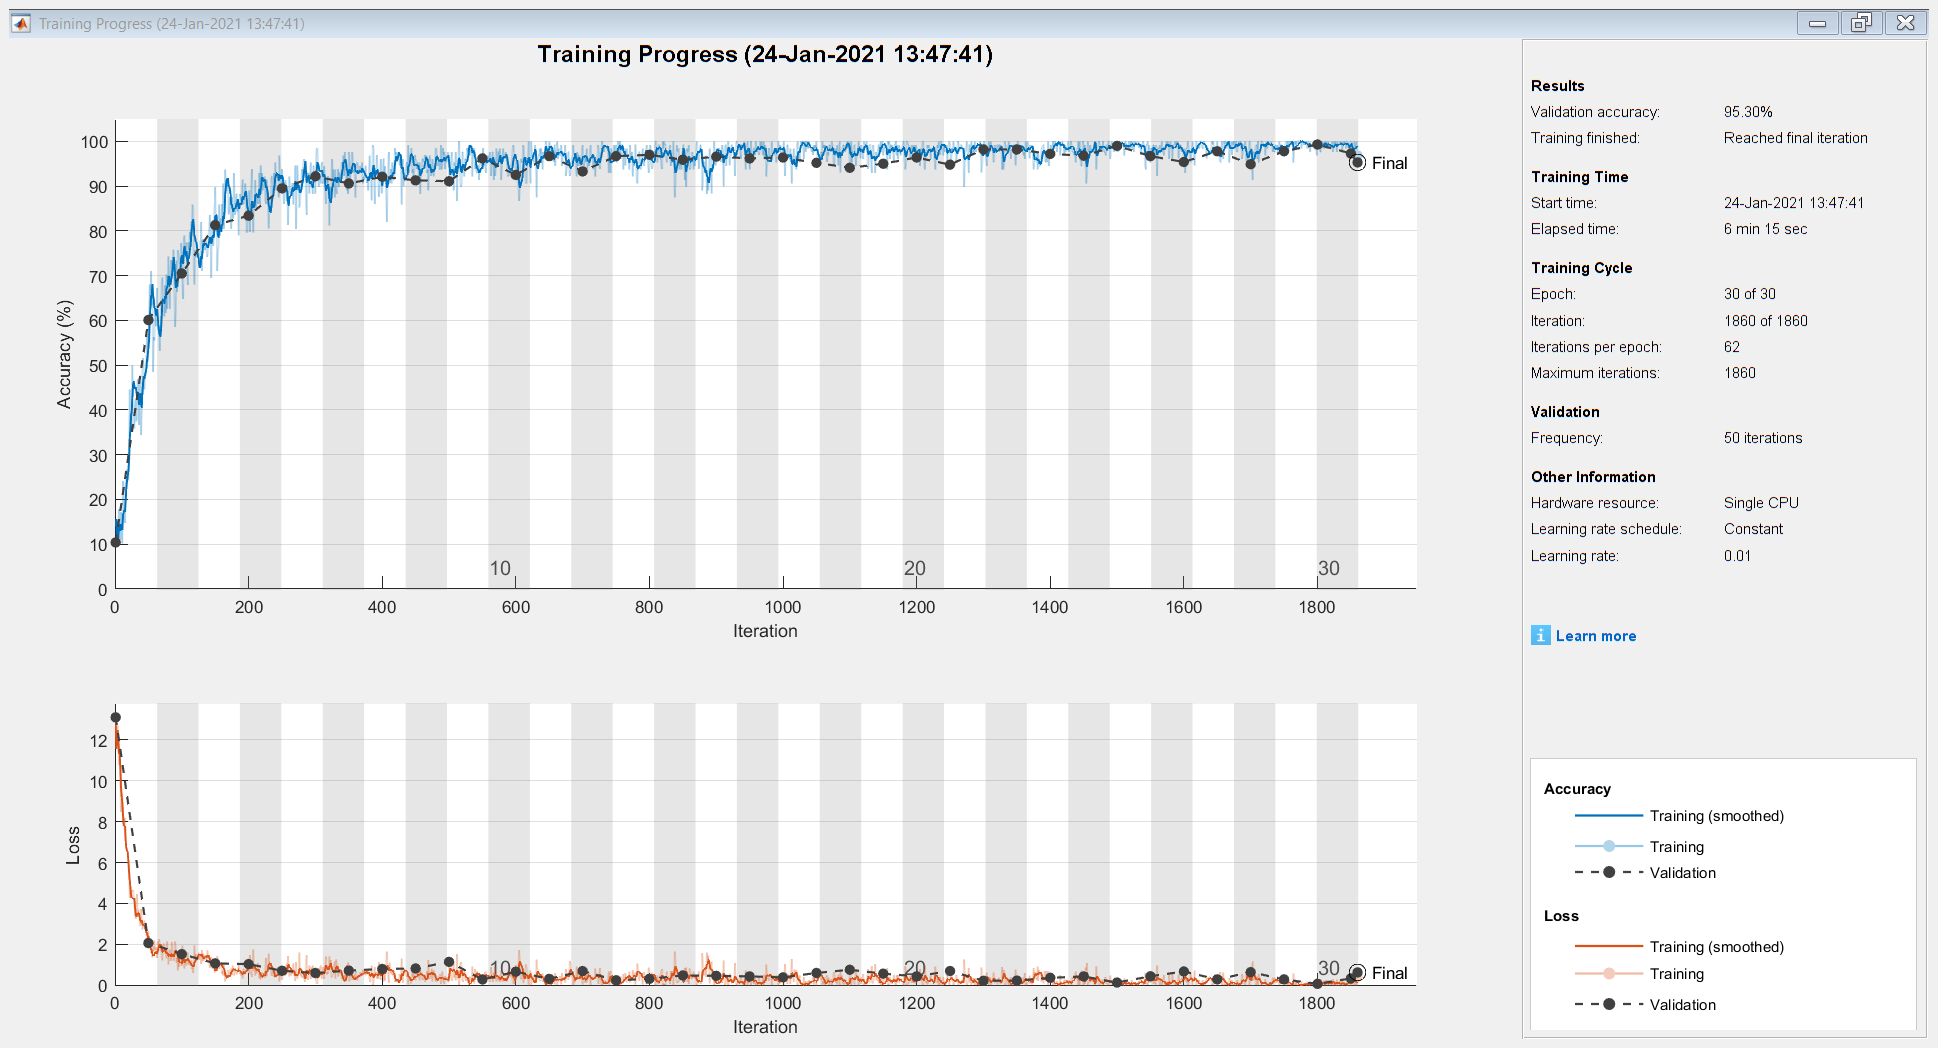

ops = trainingOptions("sgdm","Plots","training-progress",...
    "InitialLearnRate",0.01,"GradientThreshold",2,"ValidationData",val_data,...
    "VerboseFrequency",30,"ExecutionEnvironment","auto");

net = trainNetwork(train_data, layers, ops);

Валидация

y_predict = classify(net,test_data);
acc = sum(y_predict == test_data.Labels)/numel(y_predict);
confusionmat(y_predict,test_data.Labels)

ans =     97     0     0     0     0     1     0     0     0     0
     0    96     0     0     0     0     0     0     1     3
     0     4   100     7     1     0     2     4     4     0
     0     0     0    76     0     0     0     0     0     0
     0     0     0     0    99     0     0     0     0     0
     0     0     0     4     0    97     0     0     0     0
     0     0     0     0     0     0    96     0     1     0
     0     0     0     0     0     0     0    96     0     0
     0     0     0     0     0     0     0     0    93     0
     3     0     0    13     0     2     2     0     1    97
